# AAE 567 HW3 Problem3

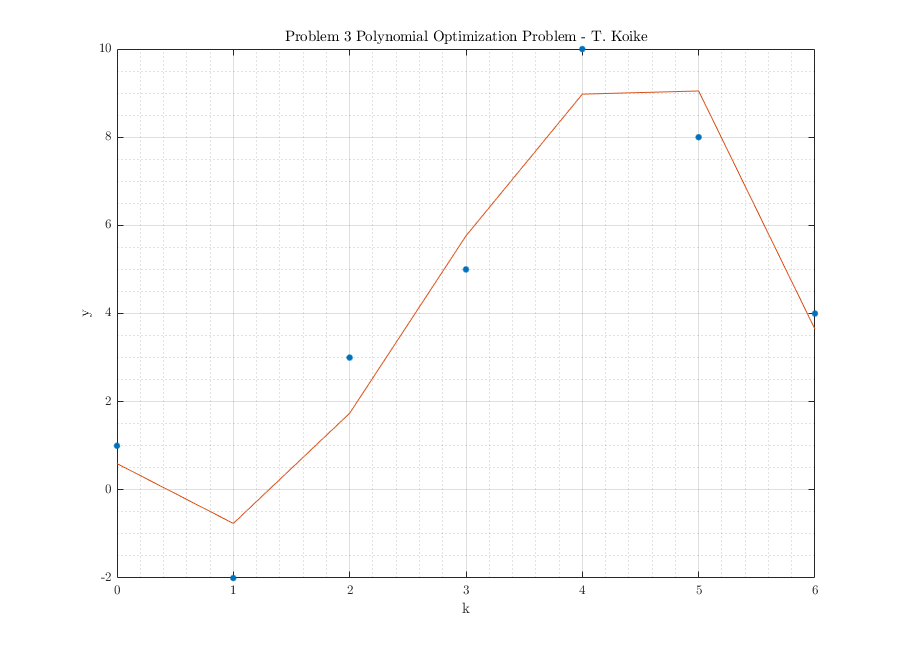

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Define given vector
y = [1 -2 3 5 10 8 4]';

% Define the Vandermonde matrix
k = [0 1 2 3 4 5 6];
V = fliplr(vander(k));
V = V(:, 1:4);
ahat = pinv(V)*y;
error2 = norm(y)^2 - dot(ahat, V'*y) ;
error = sqrt(error2);

% Plotting
fig = figure("Renderer","painters", "Position",[60 60 900 650]);
    plot(k, y, '.', "MarkerSize", 15)
    hold on; grid on; box on; grid minor;
    plot(k, polyval(flip(ahat)', k), '-')
    title("Problem 3 Polynomial Optimization Problem - T. Koike")
    xlabel('k')
    ylabel('y')
saveas(fig,"hw3_p3_polyopt.png")